rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data

load digits; clear size
X_train=X;        %  WO   noise 
X_train_v=Xtest1; % with noise 
X_test=Xtest2;    % with noise 

[N_train, dim]=size(X_train);
[N_train_v, dim]=size(X_train_v);
[N_test, dim]=size(X_test);

%Xnt = Xtest1; 
maxx=max(max(X_train_v));
noisefactor =0.3;
noise = noisefactor*maxx; % sd for Gaussian noise
Xnt = X_train_v; % add noise to the validation set 
for i=1:size(X_train_v,1)
  randn('state', i);
  Xnt(i,:) = X_train_v(i,:) + noise*randn(1,dim);
end


maxx=max(max(X_test));
noisefactor =1.5;
noise = noisefactor*maxx; % sd for Gaussian noise
Xn = X_test;  % add noise to the 'real' test set 
for i=1:X_test
  randn('state', N_train_v+i);
  Xn(i,:) = X_test(i,:) + noise*randn(1, dim);
end


sig2_l=[0.1,1,10,25,50,100,200,400];
pc_l=[2,4,8,16,32,64,128,190];
mse_l= [];


for sig2=1:length(sig2_l)
    sig2m = sig2_l(sig2);
    % kernel PCA
    [lam,U] = kpca(X_train,'RBF_kernel',sig2m,[],'eig',240); 
    [lam, ids]=sort(-lam);                              %obtienen todos los eigenvectors (despues se filtraran, no ahorita)
    U=U(:,ids);
    
 for pc=1:length(pc_l)
     pcm = pc_l(pc);
     Ud=U(:,(1:pcm)); % the eigenvectors computed from non-noisy data
     
     X_val_denoised=[];
     for i=1:10 % for every digit
       x_it=X_train_v(i,:); % noisy data 
       X_val_denoised(i,:) = preimage_rbf(X_train,sig2m,Ud,x_it,'denoise');
     end
     
     %mse normaløized with the size of the matrix
     mse_l(sig2,pc)=sum(sum((X_train_v-X_val_denoised).^2))/(240*10);

     disp(['Loop at sig2: ', num2str(sig2m), ' with PC: ', num2str(pcm)])
 
 end 
end 

    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 2


    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 4


    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 8


    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 16


    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 32


    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 64


    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 128


    0> Starting value changed!(d=0) 
    1> Starting value changed!(d=0) 
    2> Starting value changed!(d=0) 
    3> Starting value changed!(d=0) 
    4> Starting value changed!(d=0) 
    5> Starting value changed!(d=0) 
    6> Starting value changed!(d=0) 
    7> Starting value changed!(d=0) 
    8> Starting value changed!(d=0) 
    9> Starting value changed!(d=0) 
   10> Starting value changed!(d=0) 
   11> Starting value changed!(d=0) 
   12> Starting value changed!(d=0) 
   13> Starting value changed!(d=0) 
   14> Starting value changed!(d=0) 
   15> Starting value changed!(d=0) 
   16> Starting value changed!(d=0) 
   17> Starting value changed!(d=0) 
   18> Starting value changed!(d=0) 
   19> Starting value changed!(d=0) 
   20> Starting value changed!(d=0) 
   21> Starting value changed!(d=0) 
   22> Starting value changed!(d=0) 
   23> Starting value changed!(d=0) 
   24> Starting value changed!(d=0) 
   25> Starting value changed!(d=0) 
   26> Starting value changed!(d=0) 
 

Loop at sig2: 0.1 with PC: 190
Loop at sig2: 1 with PC: 2
Loop at sig2: 1 with PC: 4
Loop at sig2: 1 with PC: 8
Loop at sig2: 1 with PC: 16
Loop at sig2: 1 with PC: 32
Loop at sig2: 1 with PC: 64
Loop at sig2: 1 with PC: 128
Loop at sig2: 1 with PC: 190
Loop at sig2: 10 with PC: 2
Loop at sig2: 10 with PC: 4
Loop at sig2: 10 with PC: 8
Loop at sig2: 10 with PC: 16
Loop at sig2: 10 with PC: 32
Loop at sig2: 10 with PC: 64
Loop at sig2: 10 with PC: 128
Loop at sig2: 10 with PC: 190
Loop at sig2: 25 with PC: 2
Loop at sig2: 25 with PC: 4
Loop at sig2: 25 with PC: 8
Loop at sig2: 25 with PC: 16
Loop at sig2: 25 with PC: 32
Loop at sig2: 25 with PC: 64
Loop at sig2: 25 with PC: 128
Loop at sig2: 25 with PC: 190
Loop at sig2: 50 with PC: 2
Loop at sig2: 50 with PC: 4
Loop at sig2: 50 with PC: 8
Loop at sig2: 50 with PC: 16
Loop at sig2: 50 with PC: 32
Loop at sig2: 50 with PC: 64
Loop at sig2: 50 with PC: 128
Loop at sig2: 50 with PC: 190
Loop at sig2: 100 with PC: 2
Loop at sig2: 100 with P

 1000> Maximum iteration reached!


Loop at sig2: 200 with PC: 2
Loop at sig2: 200 with PC: 4
Loop at sig2: 200 with PC: 8
Loop at sig2: 200 with PC: 16
Loop at sig2: 200 with PC: 32
Loop at sig2: 200 with PC: 64
Loop at sig2: 200 with PC: 128
Loop at sig2: 200 with PC: 190


 1000> Maximum iteration reached!


Loop at sig2: 400 with PC: 2


  501> Starting value changed!(d=0) 
  503> Starting value changed!(d=0) 
 1000> Maximum iteration reached!


Loop at sig2: 400 with PC: 4


  501> Starting value changed!(d=0) 


Loop at sig2: 400 with PC: 8
Loop at sig2: 400 with PC: 16
Loop at sig2: 400 with PC: 32
Loop at sig2: 400 with PC: 64
Loop at sig2: 400 with PC: 128
Loop at sig2: 400 with PC: 190


mse_l

mse_l =     0.2821    0.2644    0.2773    0.2790    0.2790    0.2656    0.2854    0.2916
    0.1483    0.1483    0.1483    0.1483    0.1483    0.1483    0.1483    0.1483
    0.2012    0.1880    0.1765    0.1569    0.1406    0.1411    0.1421    0.1457
    0.2043    0.1529    0.1294    0.1111    0.1007    0.0995    0.1063    0.1104
    0.2075    0.1518    0.1279    0.1015    0.0903    0.0880    0.0870    0.0892
    0.2536    0.1836    0.1491    0.1119    0.0975    0.0925    0.0910    0.0911
    0.3670    0.2881    0.2385    0.1858    0.1616    0.1493    0.1466    0.1466
    0.6347    0.5565    0.6147    0.4111    0.3738    0.3486    0.3371    0.3378


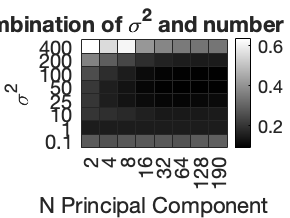

h = heatmap(mse_l);
h.XDisplayLabels = string(pc_l);
h.YDisplayLabels = string(sig2_l);
h.YDisplayData = flipud(h.YDisplayData);
h.NodeChildren(3).YDir='normal';  
title('Best parmeters for combination of \sigma^2 and number of principal components');
xlabel('N Principal Component');
ylabel('\sigma^2');
colormap(gray);
exportgraphics(h,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_321_6.png','Resolution',300)

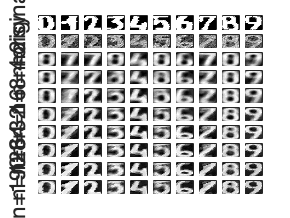

nb_pcs = 2


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 4


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 8


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 16


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 32


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 64


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 128


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

nb_pcs = 190


digit 0 : digit 1 : digit 2 : digit 3 : digit 4 : digit 5 : digit 6 : digit 7 : digit 8 : digit 9 : 

% which number of eigenvalues of kpca
pc_l=[2,4,8,16,32,64,128,190];
lpcs = length(pc_l);

%% define sigma squared
sig2=50;

[lam,U] = kpca(X_train,'RBF_kernel',sig2,[],'eig',240); 
[lam, ids]=sort(-lam);                              
lam = -lam; 
U=U(:,ids);
    
% choose the digits for test
digs=[0:9]; 
ndig=length(digs);
m=2; % Choose the mth data for each digit 
Xdt=zeros(ndig,dim);

figure; 
colormap('gray'); 
title('Denosing using linear PCA'); 

for k=1:lpcs
 nb_pcs=pc_l(k); 
 disp(['nb_pcs = ', num2str(nb_pcs)]); 
 Ud=U(:,(1:nb_pcs)); lamd=lam(1:nb_pcs);
    
 for i=1:ndig
   dig=digs(i);
   fprintf('digit %d : ', dig)
   xt=Xnt(i,:);
   if k==1 
     % plot the original clean digits
     %
     subplot(2+lpcs, ndig, i);
     pcolor(1:15,16:-1:1,reshape(X_test(i,:), 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     
     if i==1, ylabel('original'), end 
     
     % plot the noisy digits 
     %
     subplot(2+lpcs, ndig, i+ndig); 
     pcolor(1:15,16:-1:1,reshape(xt, 15, 16)'); shading interp; 
     set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);        
     if i==1, ylabel('noisy'), end
     drawnow
   end    
   Xdt(i,:) = preimage_rbf(X_train,sig2,Ud,xt,'denoise'); 
   subplot(2+lpcs, ndig, i+(2+k-1)*ndig);            

   pcolor(1:15,16:-1:1,reshape(Xdt(i,:), 15, 16)'); shading interp; 
   set(gca,'xticklabel',[]);set(gca,'yticklabel',[]);           
   if i==1, ylabel(['n=',num2str(nb_pcs)]); end
   drawnow    
 end 
end 

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures3/fig3_321_7.png','Resolution',300)